# [The racing diffusion model of speeded decision making](https://pubmed.ncbi.nlm.nih.gov/32424622/)

Tillman, G., Van Zandt, T. & Logan, G.D. Sequential sampling models without random between-trial variability: the racing diffusion model of speeded decision making. *Psychon Bull Rev* **27**, 911–936 (2020). https://doi.org/10.3758/s13423-020-01719-6

clear all
close all
addpath("utl") 

## Simulate a RDM 

#### Config parameters

a = 3; % Decision threshold
v1 = 4; % Drift rate of Accumulator 1
v0 =2.84; % Drift rate of Accumulator 0
dt = 1/60; % Sampling rate

#### Animation plot of the evidence accumulation process

tiledlayout(1,3) % create a layout for the different plots

y1 = 0; % Starting point of Accumulator 1
y0 = 0; % Starting point of Accumulator 2
x= 0; % Starting time of the accumulation process

% Initialize the plot
nexttile(1)
plot(0,[0;0])
xlim([0,3])
ylim([-1,a])
yticks([0 a])
yline(0)

waitforbuttonpress; % Press a button to start
goon =true; %Logical value to continue the animation until a mouse click
while goon
    hold on
    y1 = [y1 y1(end) + normrnd(v1*dt, sqrt(dt))]; % Diffusion process of Accumulator 1
    y0 = [y0 y0(end) + normrnd(v0*dt, sqrt(dt))]; % Diffusion process of Accumulator 2
    x = [x x(end)+dt];
    plot(x,y1,'b',x,y0,'r')
    pause(dt)
    if y1(end)>a || y0(end)>a % If any accumulator reaches the boundary, the process ends.
        g = waitforbuttonpress;
        if g == 1 % If a key is pressed, a new process is simulated
            y1 = 0;
            y0 = 0;
            x= 0;
        else % if the mouse is clicked, the simulation ends
            goon = false;
        end
    end
end

## Plots of the response time (RT) distributions for the two accumulators

#### Data simulation

ntrials = 1000; % Number of simulated trials
% Initialize  RT and Response vectors
rt = nan(ntrials,1);
resp = false(ntrials,1);
for idx = 1:ntrials
    x=0;
    y1 = 0;
    y0 = 0;
    goon =true;
    while goon
        y1 = [y1 y1(end) + normrnd(v1*dt, sqrt(dt))];
        y0 = [y0 y0(end) + normrnd(v0*dt, sqrt(dt))];
        x = [x x(end)+dt];
        if y1(end)>a || y0(end)>a
            rt(idx) = x(end);
            resp(idx) = y1(end)>a;
            goon = false;
        end
    end
end

#### Display the distributions

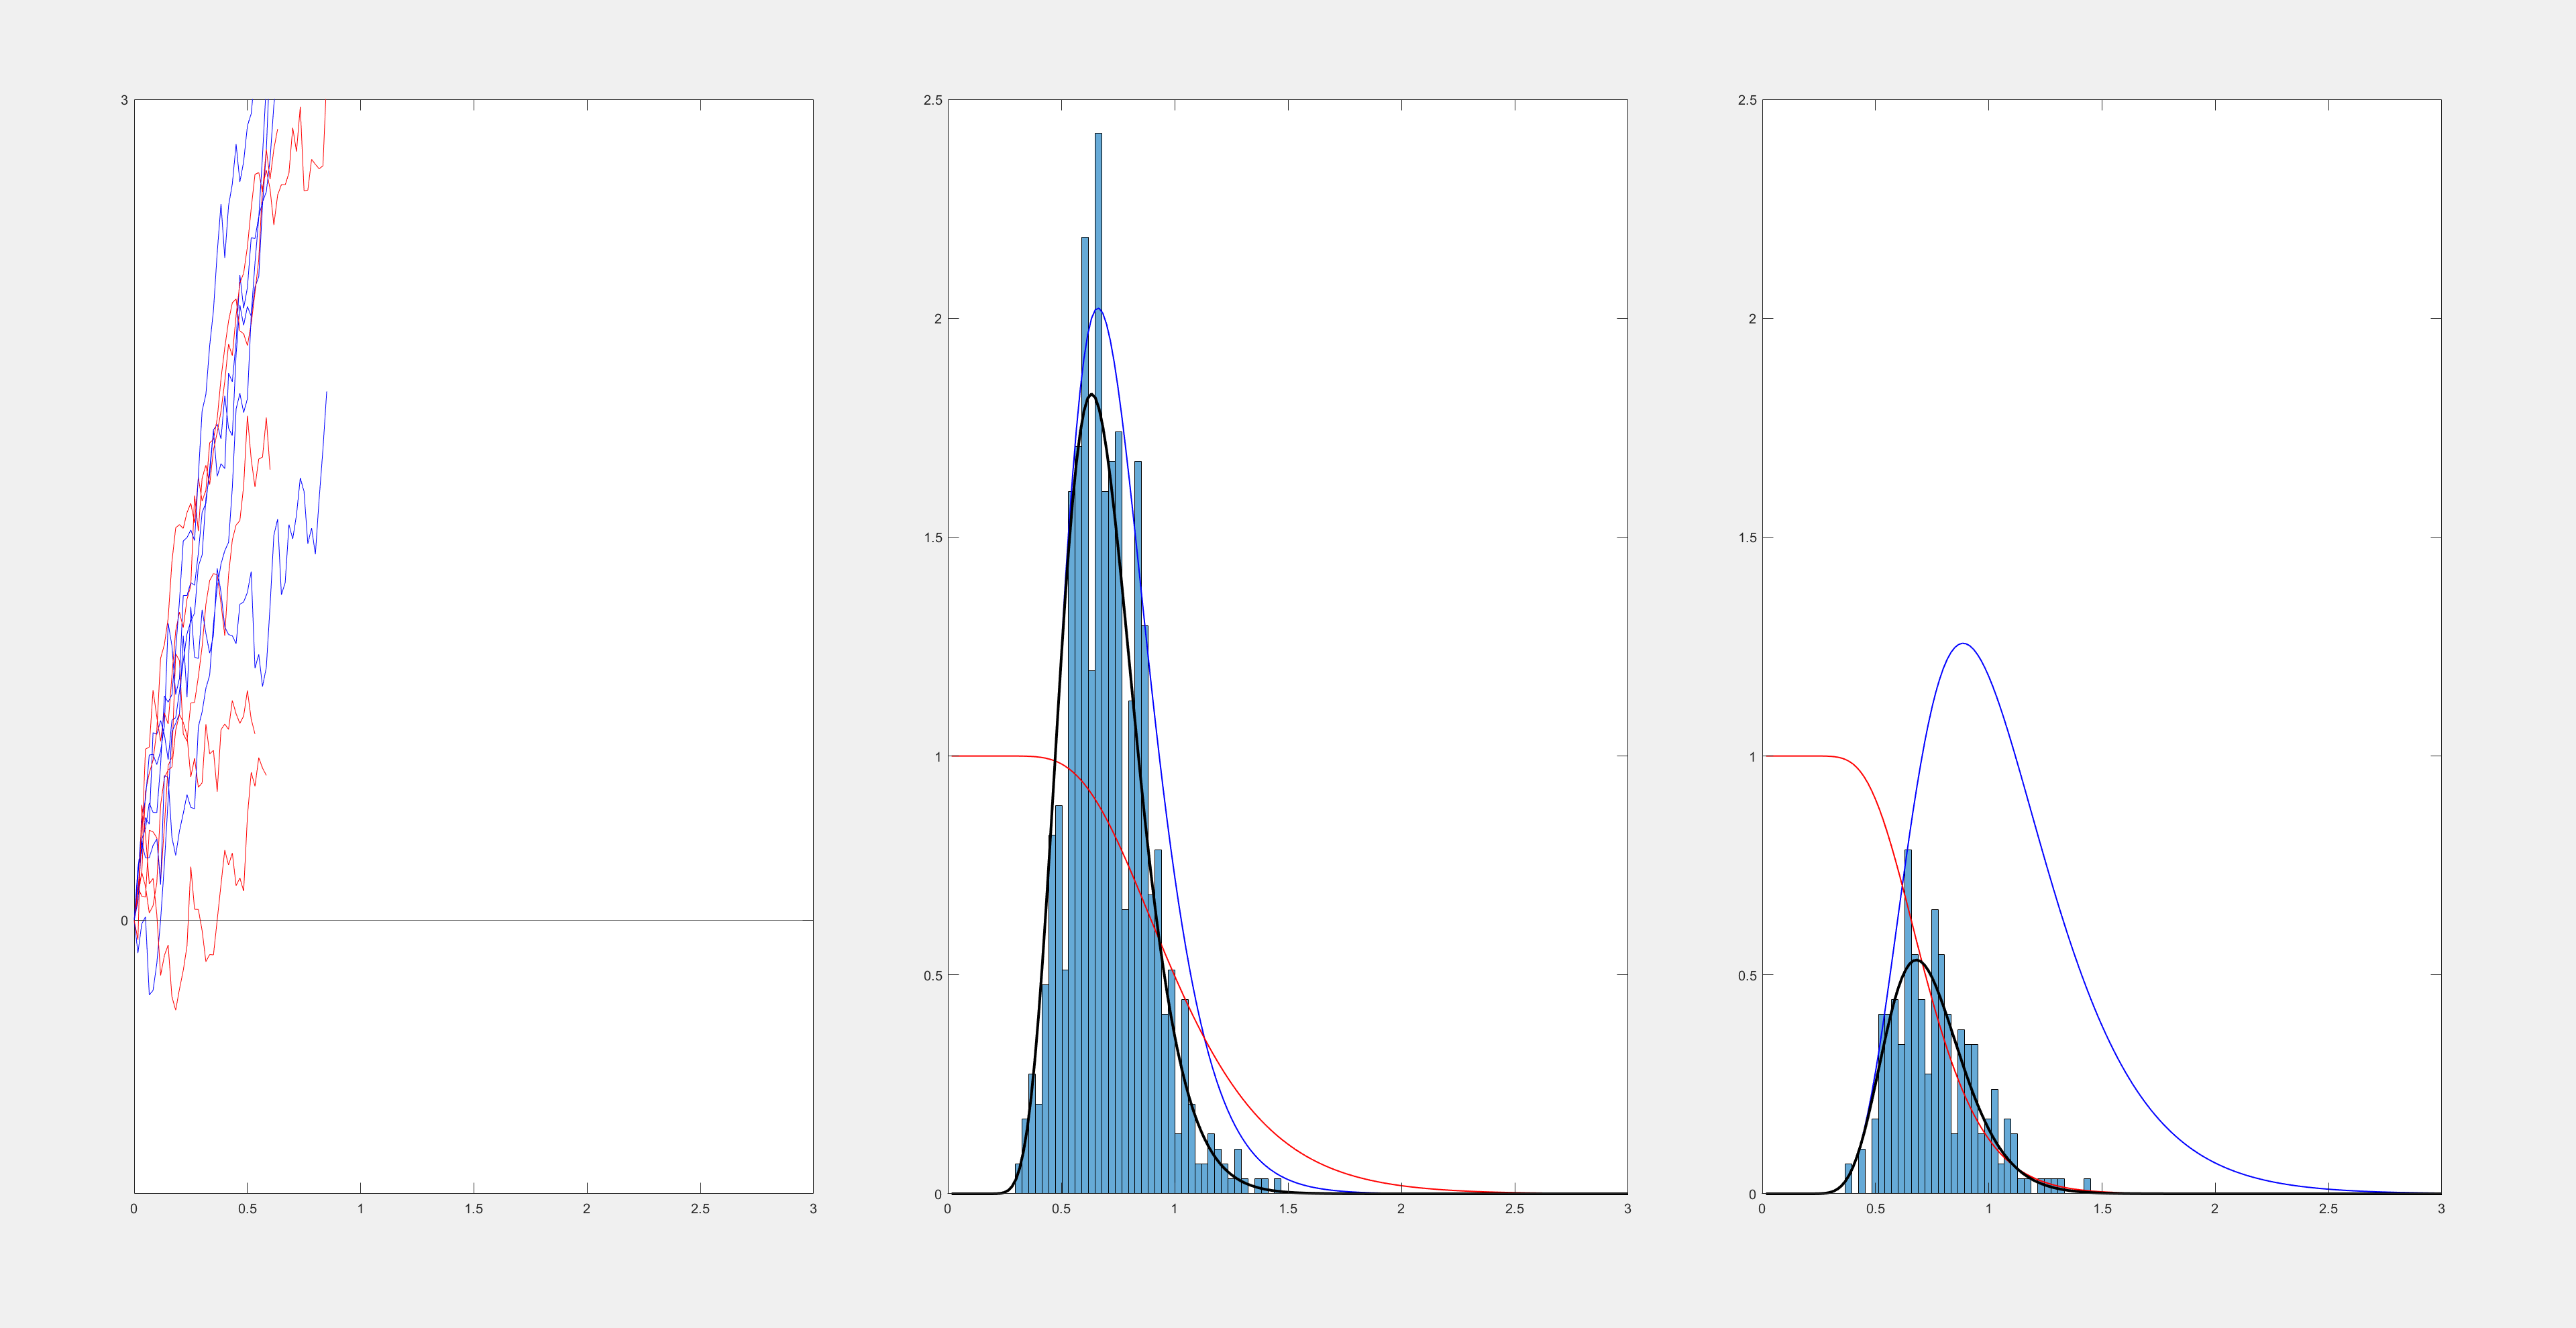

% Accumulator 1
waitforbuttonpress;
nexttile(2)
rt1 = rt; rt1(~resp)=-rt1(~resp); % Trick to display a PDF histogram weighted by the proportion of wins.
histogram(rt1,ntrials/10,Normalization="pdf"), xlim([0 3]),
x = dt:dt:3; 
% Compute:
% - Wald probability density (PDF) of Accumulator 1
% - Cumulative distribution function (CDF) of Accumulator 2
% - Defective probability density function (g) of Accumulator 1
[g, pdf, cdf]= utl_inverse_gaussian_defective(x,v1,v0,a,a);
waitforbuttonpress;
hold on, 
plot(x,pdf,"b",LineWidth=1) % Plot finishing time distribution of Accumulator 1 (i.e. PDF)
plot(x,1-cdf,"r",LineWidth=1) % Plot survival distribution of Accumulator 2 (i.e. 1- CDF)
plot(x,g,"k",LineWidth=2) % Plot first-passage time distributions of Accumulator 1 (i.e. g)

% Accumulator 2
waitforbuttonpress;
nexttile(3)
rt2 = rt; rt2(resp)=-rt2(resp);
histogram(rt2,ntrials/10,Normalization="pdf"), xlim([0 3])
[g, pdf, cdf]= utl_inverse_gaussian_defective(x,v0,v1,a,a);
waitforbuttonpress;
hold on, 
plot(x,pdf,"b",LineWidth=1) % Plot finishing time distribution of Accumulator 1 (i.e. PDF)
plot(x,1-cdf,"r",LineWidth=1) % Plot survival distribution of Accumulator 2 (i.e. 1- CDF)
plot(x,g,"k",LineWidth=2)


% Display mean RT and accuracy
clc
disp('Results:');

Results:


disp(' ')

disp('Correct responses:');

Correct responses:


disp(['Mean RT: ' num2str(mean(rt(resp)))])

Mean RT: 0.71134


disp(['Proportion of correct responses: ' num2str(mean(resp))])

Proportion of correct responses: 0.767


disp(' ')

disp('Incorrect responses:');

Incorrect responses:


disp(['Mean RT: ' num2str(mean(rt(~resp)))])

Mean RT: 0.76073


disp(['Proportion of errors: ' num2str(mean(~resp))])

Proportion of errors: 0.233


## RDM parameter estimation

x0 = [0 0 0]; % set initial points
fun = @(x) -fit_RDM(x,rt,resp); % Function to be minimized
options = optimoptions('fminunc', 'Algorithm', 'quasi-newton'); % Choose the optimization algorithm
x = fminunc(fun, x0, options); % Parameter estimation


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


% Extract results
p_ddm.a = exp(x(1)); % Transform the estimated parameters to their native space.
p_ddm.v1 = exp(x(2));
p_ddm.v0 = exp(x(3));
disp('Results:');

Results:


disp(' ')

disp('Parameter estimates:');

Parameter estimates:


disp(p_ddm)

     a: 3.0810
    v1: 3.9911
    v0: 2.8642

